clear;
clc;

addpath('D:\Matlab\symnmf-master');
data = importdata('flame.txt');
X = data(:, 1:2);
label = data(:, 3);

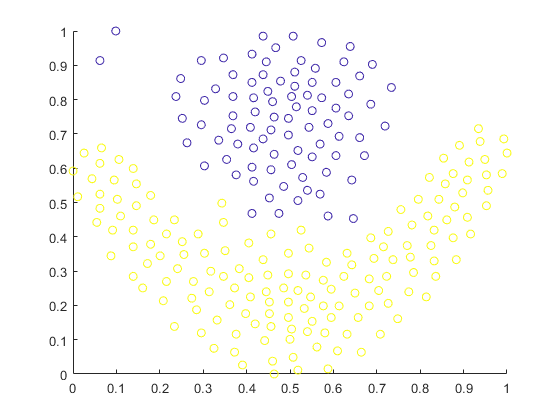

%% 归一化
[row, col] = size(X);
m1 = max(X, [], 1);
m2 = min(X, [], 1);
X = (X - m2) ./ (m1 - m2);

scatter(X(:, 1), X(:, 2), [], label);

%% 构建基于KNN图的稀疏相似度矩阵
sigma = 0.5;

% 邻域范围
Neighbor = 20;
[idx, D] = knnsearch(X, X, 'K', Neighbor);
D = exp(-(D / sigma) .^ 2);

ilist = repmat(idx(:, 1), Neighbor, 1);
jlist = idx(:);
vlist = D(:);

% 构建方式一，此时W对角线为2
W = sparse(ilist, jlist, vlist, size(X, 1), size(X, 1));
W = W + W';

% 构建方式二，此时W对角线为1

% vision = [ilist, jlist, vlist];
% vision_exchange = vision;
% vision_exchange(:, [1, 2]) = vision_exchange(:, [2, 1]);
% 
% vision_all = [vision; vision_exchange];
% v = unique(vision_all, 'rows');
% W = sparse(v(:, 1), v(:, 2), v(:, 3), size(X, 1), size(X, 1));

% 相似度矩阵归一化
T = 1./sum(W);
T_temp = sqrt(W);
W = T_temp' .* W .* T_temp;

%% 对称非负矩阵分解，SymNMF
% 低秩矩阵H的秩
k = 2;
[H, ~] = symnmf_anls(W, k, ['var']);

%% 基于低秩矩阵H的CCE
kmin = 1;
interval = 0.1;
kmax = 10;
classnum = length(unique(label));

% 看类别数目
v = LMCCE_cnum(H, kmin, interval, kmax);

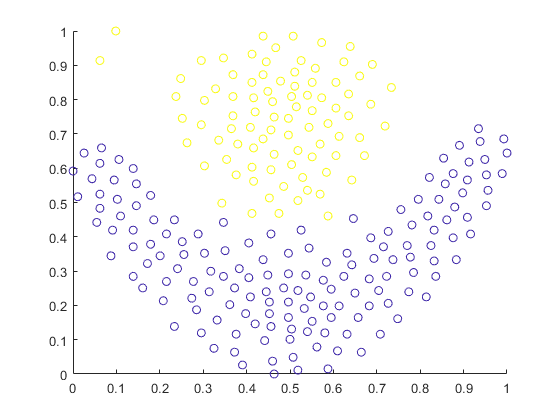

% 类别数包含需要的，继续
[label_lmcce, ~, ~, ~, ~] = LMCCE(H, kmin, interval, kmax, classnum);

% 统一标签和label一致
% [~, lmcce] = label_corrected(label_lmcce, label);
% [OA, Kappa, PA, UA] = calaccuracy(gt, lmcce)
% [ARI_lmcce, ~] = ari(gt, lmcce)

scatter(X(:, 1), X(:, 2), [], label_lmcce);